clc,clear;
close all
syms theta1 theta2 theta3 r0 r1 r2 r3  ;



r1 = 4.5;
r2 = 3.2;
r3 = 4.5;
r0 = 8.8;
th2=[];
th3=[];
w = rad2deg(-0.5)

w = -28.6479

w1 = w;
assert (r1 + r2 + r3 > r0,"Not a valid Mechanism")
assert (r0 + r2 + r3 > r1,"Not a valid Mechanism")
assert (r1 + r0 + r3 > r2,"Not a valid Mechanism")
assert (r1 + r2 + r0 > r3,"Not a valid Mechanism")

%Limiting angles for theta 1

theta1max = acos((r0^2 + r1^2 -  ((r3 + r2)^2))/(2*r1*r0))

theta1max = 1.0646

tmd = rad2deg(theta1max)

tmd = 60.9975

tmdi = -tmd

tmdi = -60.9975

time = -(tmd - tmdi)/w

time = 4.2584

t=0:0.1:time

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000





th1=( w*t + tmd)

th1 =    60.9975   58.1327   55.2679   52.4031   49.5383   46.6735   43.8087   40.9439   38.0791   35.2144   32.3496   29.4848   26.6200   23.7552   20.8904   18.0256   15.1608   12.2960    9.4313    6.5665    3.7017    0.8369   -2.0279   -4.8927   -7.7575  -10.6223  -13.4871  -16.3518  -19.2166  -22.0814  -24.9462  -27.8110  -30.6758  -33.5406  -36.4054  -39.2702  -42.1349  -44.9997  -47.8645  -50.7293  -53.5941  -56.4589  -59.3237





%Vector loop equations

F(1) = r1*cos(theta1) + r2*cos(theta2) == r0+ r3*cos(theta3)

$$F = \frac{9\,\cos\left(\theta_{1}\right)}{2}+\frac{16\,\cos\left(\theta_{2}\right)}{5}=\frac{9\,\cos\left(\theta_{3}\right)}{2}+\frac{44}{5}$$

F(2) = r1*sin(theta1) + r2*sin(theta2) == 0+ r3*sin(theta3);


%Create the initial point x0.  

x0 = [360 - (180 - (tmd/2));180 - (tmd/2)]

x0 =   210.4987
  149.5013



    
for i=1:length(th1)

    theta1 = th1(i)
    F = @(x) [+r1*cosd(theta1) + r2*cosd(x(1)) - r3*cosd(x(2)) - r0;
             +r1*sind(theta1) + r2*sind(x(1)) - r3*sind(x(2))];

     
    %Set options to return iterative display.

    options = optimoptions('fsolve','Display','iter');
    
    %Solve the equations.

    [x,fval] = fsolve(F,x0);
    th2 = [th2 x(1)] ;
    th3 = [th3 x(2)] ;
    x0 = [double(x(1));double(x(2))]
    disp( "pop")
end

theta1 = 60.9975


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x0 =   328.4418
  149.8435


pop


theta1 = 58.1327


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x0 =   312.7346
  160.9157


pop


theta1 = 55.2679


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x0 =   305.8413
  165.7964


pop


theta1 = 52.4031


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x0 =   300.5836
  169.6224


pop


theta1 = 49.5383


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x0 =   296.2213
  172.9401


pop


theta1 = 46.6735


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x0 =   292.4781
  175.9647


pop


theta1 = 43.8087


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x0 =   289.2218
  178.8090


pop


theta1 = 40.9439


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x0 =   286.3824
  181.5426


pop


theta1 = 38.0791


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x0 =   283.9224
  184.2134


pop


theta1 = 35.2144


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x0 =   281.8237
  186.8567


pop


theta1 = 32.3496


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x0 =   280.0808
  189.5001


pop


theta1 = 29.4848


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x0 =   278.6971
  192.1659


pop


theta1 = 26.6200


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x0 =   277.6818
  194.8719


pop


theta1 = 23.7552


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x0 =   277.0485
  197.6323


pop


theta1 = 20.8904


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x0 =   276.8130
  200.4572


pop


theta1 = 18.0256


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x0 =   276.9910
  203.3522


pop


theta1 = 15.1608


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x0 =   277.5966
  206.3172


pop


theta1 = 12.2960


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x0 =   278.6392
  209.3458


pop


theta1 = 9.4313


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x0 =   280.1216
  212.4240


pop


theta1 = 6.5665


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x0 =   282.0370
  215.5294


pop


theta1 = 3.7017


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x0 =   284.3681
  218.6313


pop


theta1 = 0.8369


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x0 =   287.0858
  221.6916


pop


theta1 = -2.0279


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x0 =   290.1502
  224.6660


pop


theta1 = -4.8927


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x0 =   293.5126
  227.5069


pop


theta1 = -7.7575


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x0 =   297.1190
  230.1668


pop


theta1 = -10.6223


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x0 =   300.9137
  232.6010


pop


theta1 = -13.4871


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x0 =   304.8431
  234.7705


pop


theta1 = -16.3518


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x0 =   308.8596
  236.6437


pop


theta1 = -19.2166


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x0 =   312.9229
  238.1971


pop


theta1 = -22.0814


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x0 =   317.0024
  239.4154


pop


theta1 = -24.9462


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x0 =   321.0768
  240.2897


pop


theta1 = -27.8110


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x0 =   325.1343
  240.8169


pop


theta1 = -30.6758


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x0 =   329.1720
  240.9974


pop


theta1 = -33.5406


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x0 =   333.1955
  240.8329


pop


theta1 = -36.4054


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x0 =   337.2187
  240.3249


pop


theta1 = -39.2702


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x0 =   341.2647
  239.4723


pop


theta1 = -42.1349


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x0 =   345.3674
  238.2683


pop


theta1 = -44.9997


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x0 =   349.5753
  236.6966


pop


theta1 = -47.8645


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x0 =   353.9600
  234.7247


pop


theta1 = -50.7293


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x0 =   358.6337
  232.2903


pop


theta1 = -53.5941


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x0 =   363.7932
  229.2697


pop


theta1 = -56.4589


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x0 =   369.8542
  225.3805


pop


theta1 = -59.3237


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x0 =   378.1596
  219.6752


pop


th1

th1 =    60.9975   58.1327   55.2679   52.4031   49.5383   46.6735   43.8087   40.9439   38.0791   35.2144   32.3496   29.4848   26.6200   23.7552   20.8904   18.0256   15.1608   12.2960    9.4313    6.5665    3.7017    0.8369   -2.0279   -4.8927   -7.7575  -10.6223  -13.4871  -16.3518  -19.2166  -22.0814  -24.9462  -27.8110  -30.6758  -33.5406  -36.4054  -39.2702  -42.1349  -44.9997  -47.8645  -50.7293  -53.5941  -56.4589  -59.3237


th2

th2 =   328.4418  312.7346  305.8413  300.5836  296.2213  292.4781  289.2218  286.3824  283.9224  281.8237  280.0808  278.6971  277.6818  277.0485  276.8130  276.9910  277.5966  278.6392  280.1216  282.0370  284.3681  287.0858  290.1502  293.5126  297.1190  300.9137  304.8431  308.8596  312.9229  317.0024  321.0768  325.1343  329.1720  333.1955  337.2187  341.2647  345.3674  349.5753  353.9600  358.6337  363.7932  369.8542  378.1596


th3

th3 =   149.8435  160.9157  165.7964  169.6224  172.9401  175.9647  178.8090  181.5426  184.2134  186.8567  189.5001  192.1659  194.8719  197.6323  200.4572  203.3522  206.3172  209.3458  212.4240  215.5294  218.6313  221.6916  224.6660  227.5069  230.1668  232.6010  234.7705  236.6437  238.1971  239.4154  240.2897  240.8169  240.9974  240.8329  240.3249  239.4723  238.2683  236.6966  234.7247  232.2903  229.2697  225.3805  219.6752



% Coordinates A B C D 
B=[]


B =

     []



C=[]


C =

     []




A=[0,0].*ones(size(th1))'

A =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


D=[r0,0].*ones(size(th1))'

D = 43×2
    8.8000         0
    8.8000         0
    8.8000         0
    8.8000         0
    8.8000         0
    8.8000         0
    8.8000         0
    8.8000         0
    8.8000         0
    8.8000         0



for i=1:length(th1)
B=[ B ;[r1*cosd(th1(i)),r1*sind(th1(i))] ] ; 

C=[ C ;[(r0 +  r3*cosd(th3(i))),r3*sind(th3(i))]] ;

end
B

B = 43×2
    2.1818    3.9357
    2.3758    3.8217
    2.5638    3.6982
    2.7455    3.5655
    2.9202    3.4238
    3.0877    3.2736
    3.2474    3.1151
    3.3991    2.9489
    3.5422    2.7754
    3.6765    2.5949


C

C = 43×2
    4.9090    2.2606
    4.5473    1.4713
    4.4376    1.1042
    4.3736    0.8106
    4.3341    0.5531
    4.3112    0.3167
    4.3010    0.0935
    4.3016   -0.1211
    4.3122   -0.3306
    4.3322   -0.5372



close all;
plot(B(:,1),B(:,2))
hold on
plot(C(:,1),C(:,2))

% for i=1:length(th1)
% x=[A(i,1) B(i,1) C(i,1) D(i,1)];
% y=[A(i,2) B(i,2) C(i,2) D(i,2)];
% plot(x,y)  % to plot polygon
% 
% pause(.1)
% end


%verification
close all
for i =1:length(B)
    D(i) = sqrt((B(i,1) - C(i,1))^2 +  (B(i,2) - C(i,2))^2);
end
D

D = 43×2
    3.2006         0
    3.2000         0
    3.2000         0
    3.2000         0
    3.2000         0
    3.2000         0
    3.2000         0
    3.2000         0
    3.2000         0
    3.2000         0


for i =1:length(B)
    M(i,1) = (B(i,1) + C(i,1))/2;
    M(i,2) = (B(i,2) + C(i,2))/2;
end
M

M = 43×2
    3.5454    3.0982
    3.4616    2.6465
    3.5007    2.4012
    3.5595    2.1880
    3.6272    1.9884
    3.6994    1.7951
    3.7742    1.6043
    3.8504    1.4139
    3.9272    1.2224
    4.0043    1.0288


% plot(M(:,1),M(:,2))

[a2_1,a3_1] = calcAcc(th1,th2,th3,r1,r2,r3,w,w2_1,w3_1);

%Velocity
for i = 1:length(th1)
    A = [ r2*cosd(th2(i)) ,- r3*cosd(th3(i));...
          -r2*sind(th2(i)) ,+ r3*sind(th3(i)) ];
    B = [-r1*w1*cosd(th1(i));...
        r1*w1*sind(th1(i))];
    x = A\B;
    w2_2(i) = x(1,1);
    w3_2(i) = x(2,1);
end

%Acceleration
for i = 1:length(th1)
    A = [ r2*cosd(th2(i)) ,- r3*cosd(th3(i));...
          -r2*sind(th2(i)) ,+ r3*sind(th3(i)) ];
    
    B = [r1*w1^2*sind(th1(i)) + r2*w2_2(i)^2*sind(th2(i)) - r3*w3_2(i)^2*sind(th3(i));...
        r1*w1^2*cosd(th1(i)) + r2*w2_2(i)^2*cosd(th2(i)) - r3*w3_2(i)^2*cosd(th3(i))];
    x = A\B;
    a2_2(i) = x(1,1);
    a3_2(i) = x(2,1);
end

t1 = t

t1 =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000


t1(1) = [];
w2_2(1) = [];
w3_2(1) = [];
a2_2(1) = [];
a3_2(1) = [];

disp("Inv")

Inv


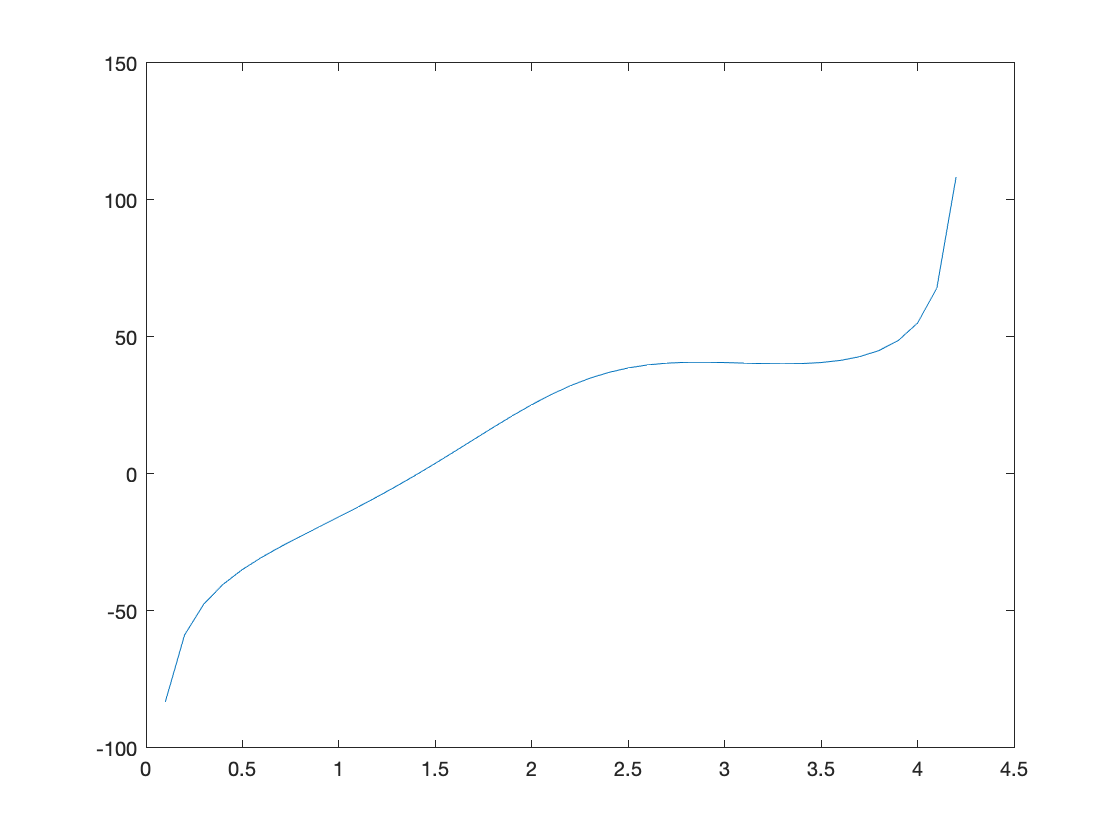


plot(t1,w2_2)

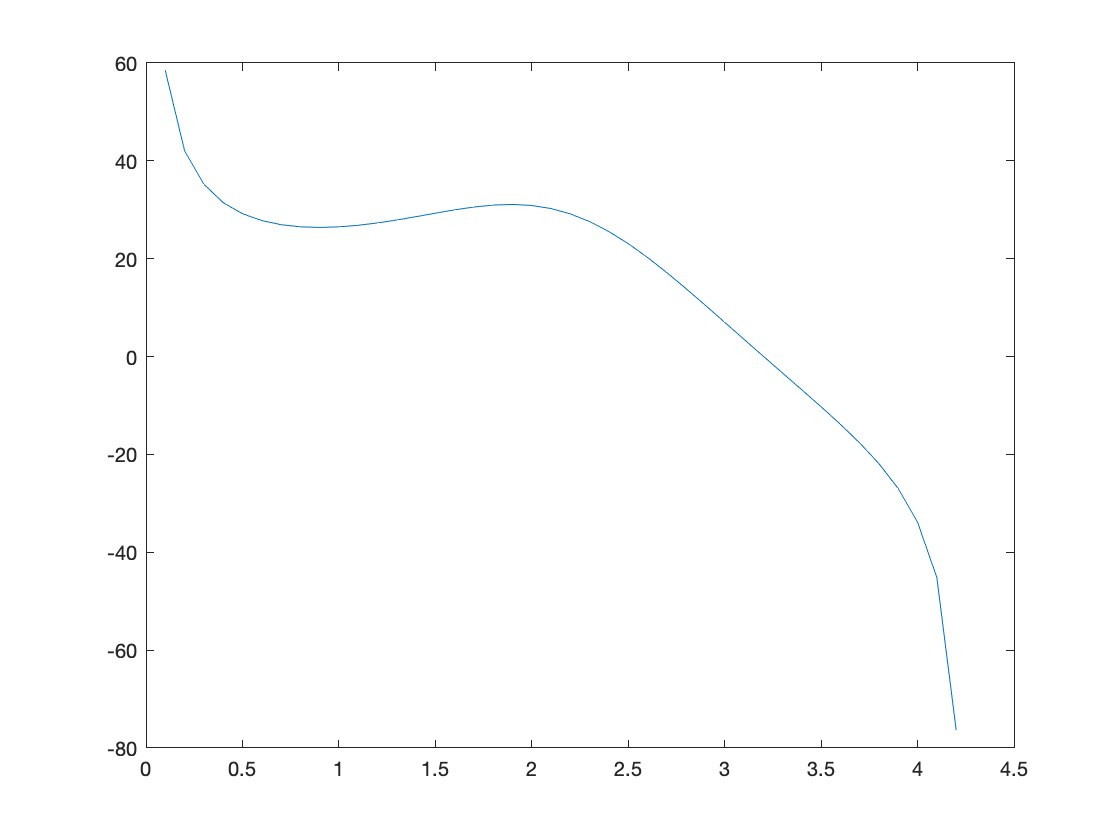


plot(t1,w3_2)

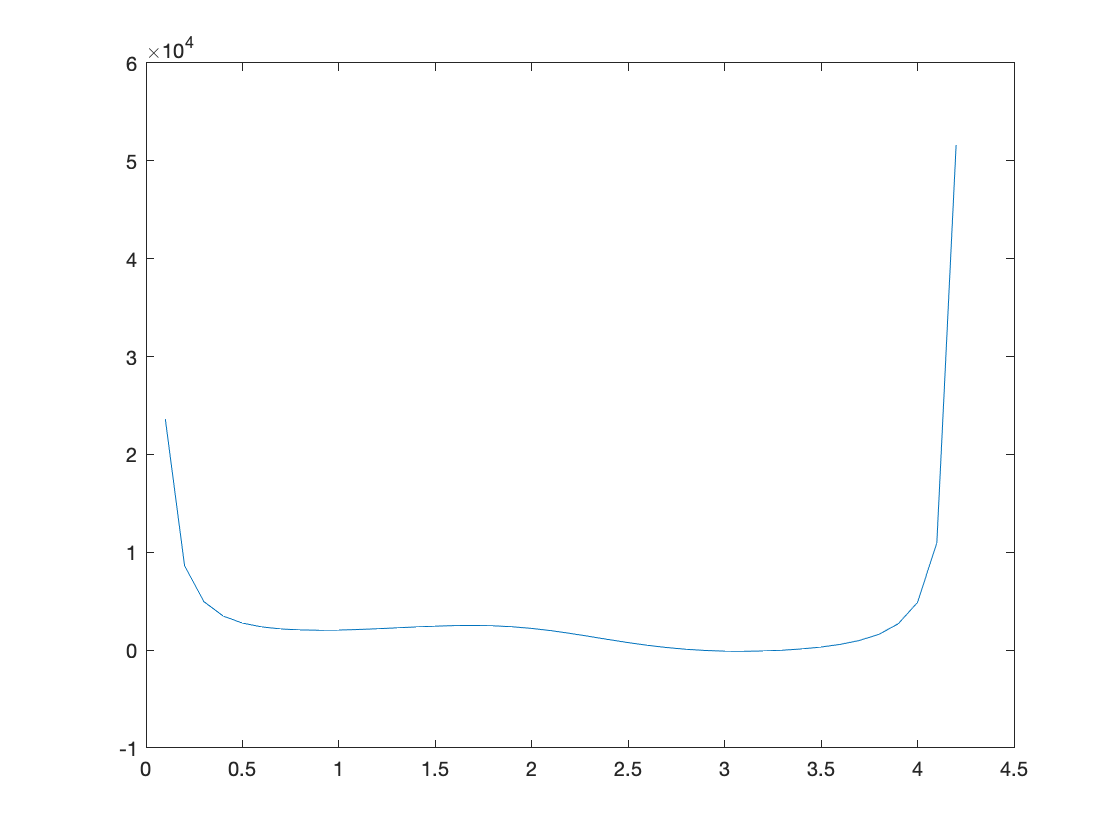


plot(t1,a2_2)

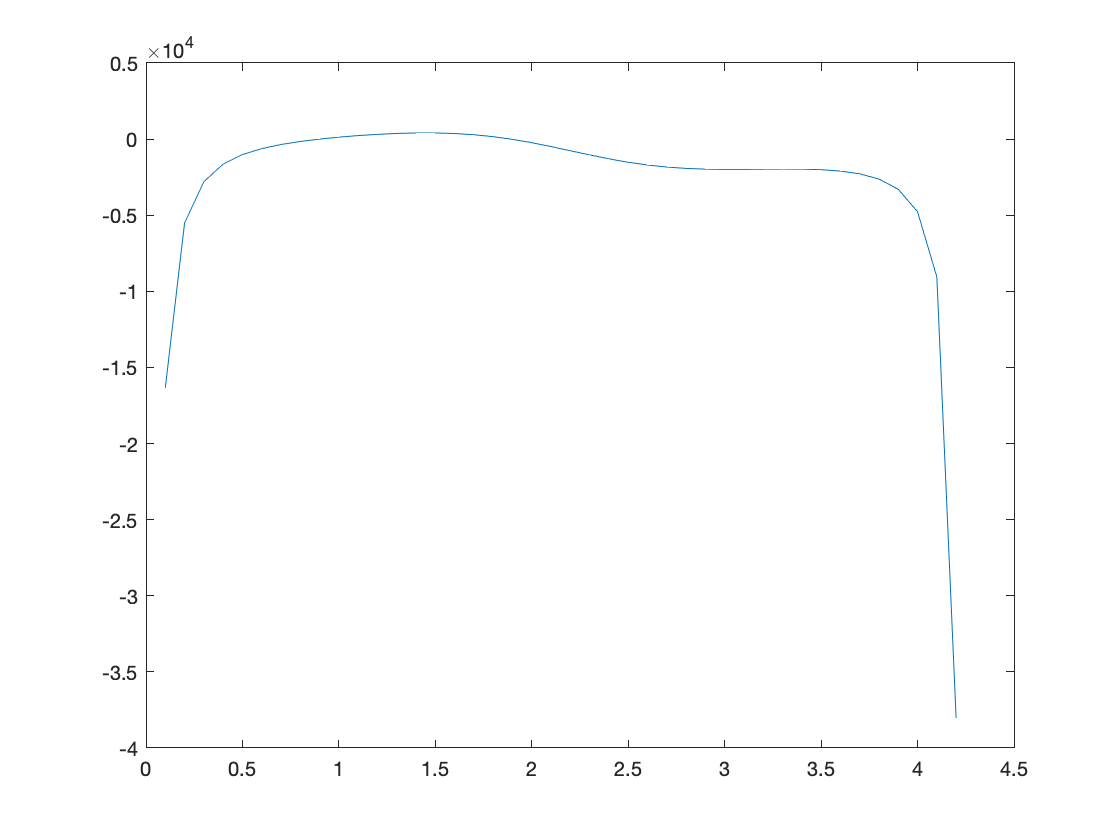

plot(t1,a3_2)

a2_2

a2_2 = 	1.0e+04 *

    2.3643    0.8626    0.4963    0.3488    0.2763    0.2374    0.2165    0.2064    0.2035    0.2055    0.2109    0.2188    0.2278    0.2371    0.2452    0.2508    0.2524    0.2487    0.2387    0.2220    0.1991    0.1711    0.1399    0.1077    0.0770    0.0494    0.0265    0.0088   -0.0034   -0.0101   -0.0118   -0.0085   -0.0005    0.0126    0.0318    0.0593    0.0995    0.1620    0.2696    0.4884    1.0974    5.1661


a3_2

a3_2 = 	1.0e+04 *

   -1.6343   -0.5509   -0.2792   -0.1638   -0.1014   -0.0624   -0.0354   -0.0154    0.0003    0.0130    0.0233    0.0314    0.0372    0.0404    0.0405    0.0368    0.0288    0.0160   -0.0016   -0.0236   -0.0491   -0.0764   -0.1039   -0.1296   -0.1520   -0.1702   -0.1836   -0.1924   -0.1973   -0.1991   -0.1988   -0.1976   -0.1967   -0.1972   -0.2009   -0.2099   -0.2280   -0.2623   -0.3296   -0.4774   -0.9057   -3.8058


function [alpha2,alpha3] = calcAcc(theta1,theta2,theta3,r1,r2,r3,w,w2,w3)
    for i = 1: length(theta1)
    syms alpha_2 alpha_3
    
    eq1 = -r1*w^2*sind(theta1(i)) ...
          + r2*alpha_2*cosd(theta2(i)) - r2*w2(i)^2*sind(theta2(i))...
          - r3*alpha_3*cosd(theta3(i)) + r3*w3(i)^2*sind(theta3(i)) == 0;
    
    eq2 = - r1*w^2*cosd(theta1(i))...
          - r2*alpha_2*sind(theta2(i)) - r2*w2(i)^2*cosd(theta2(i))...
          + r3*alpha_3*sind(theta3(i)) + r3*w3(i)^2*sind(theta3(i)) == 0;
    
    [alpha2(i),alpha3(i)] =solve([eq1,eq2],[alpha_2,alpha_3]); 
    end
end